simout = Get_Sim_Output(out)

simout = struct with fields:
     time: [194×1 double]
        x: [194×6 double]
    utraj: [100×2×188 double]
    xtraj: [100×6×188 double]


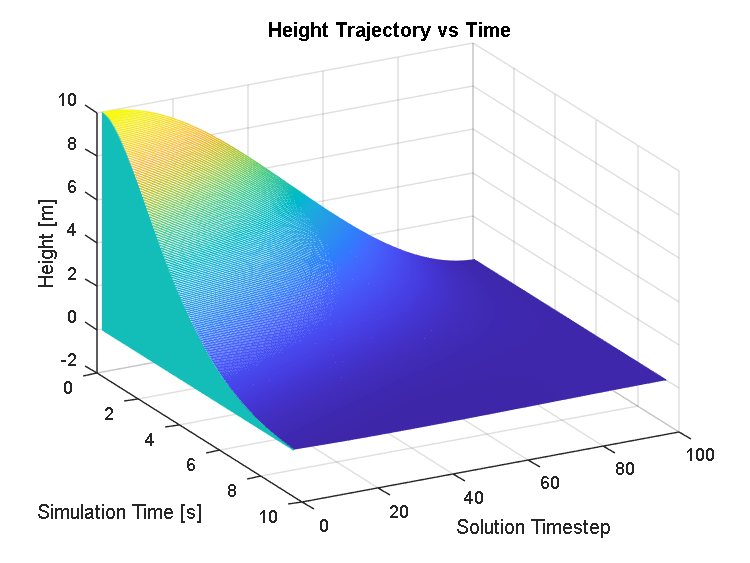


Z = squeeze(simout.xtraj(:,2,:));
[X, Y] = meshgrid(1:100,(1:188)/188 * max(simout.time));
waterfall(Y, X, Z');
xlabel("Simulation Time [s]")
ylabel("Solution Timestep")
zlabel("Height [m]")
title("Height Trajectory vs Time")

view([61.4 29.4])

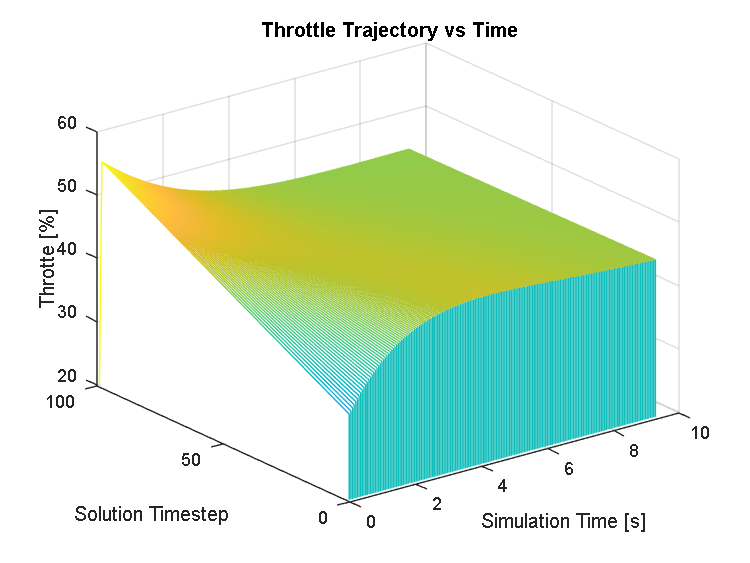

Z = squeeze(simout.utraj(:,1,:));
[X, Y] = meshgrid(1:100,(1:188)/188 * max(simout.time));
waterfall(Y, X, Z' * 100);
xlabel("Simulation Time [s]")
ylabel("Solution Timestep")
zlabel("Throtte [%]")
title("Throttle Trajectory vs Time")

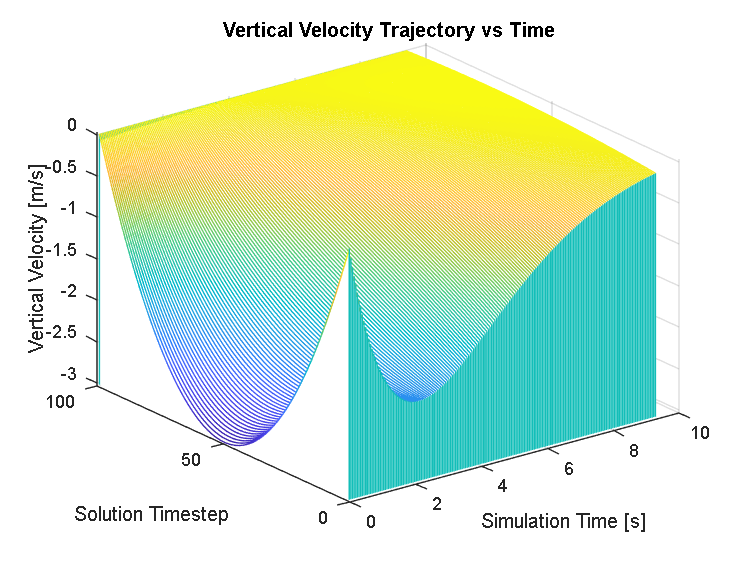

Z = squeeze(simout.xtraj(:,4,:));
[X, Y] = meshgrid(1:100,(1:188)/188 * max(simout.time));
waterfall(Y, X, Z');
xlabel("Simulation Time [s]")
ylabel("Solution Timestep")
zlabel("Vertical Velocity [m/s]")
title("Vertical Velocity Trajectory vs Time")